% Load the training data 
data = load("D:\college\FYP\50i_single.mat");
trainingData = data.trainingData;


% Create an imageDatastore using the files from the table.
imds = imageDatastore(trainingData.imageFilename);

% Create a boxLabelDatastore using the label columns from the table.
blds = boxLabelDatastore(trainingData(:,2:end));

% Combine the datastores.
ds = combine(imds, blds);

preDetector = yolov4ObjectDetector("tiny-yolov4-coco");
preDetector.Network;

% Specify the input size
inputSize = [224 224 3];

trainingDataForEstimation = transform(ds,@(data)preprocessData(data,inputSize));

numAnchors = 6;
[anchors, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);
area = anchors(:,1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:);anchors(4:6,:)};


classes = {'TrafficSign'};
preDetector = yolov4ObjectDetector("tiny-yolov4-coco",classes,anchorBoxes,InputSize=inputSize);


options = trainingOptions("sgdm", ...
    InitialLearnRate=0.0001, ...
    MiniBatchSize=16,...
    MaxEpochs=50, ...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    VerboseFrequency=5, ...
    Plots="training-progress");


*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* TrafficSign

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      2          5         00:01:12       0.0001         38.393   
      3         10         00:01:43       0.0001         8.7106   
      4         15         00:02:12       0.0001         8.6142   
      5         20         00:02:35       0.0001         4.5751   
      7         25         00:03:03       0.0001         6.9374   
      8         30         00:03:39       0.0001         3.9593   
      9         35         00:04:02       0.0001         4.267    
     10         40         00:04:24       0.0001         1.6448   

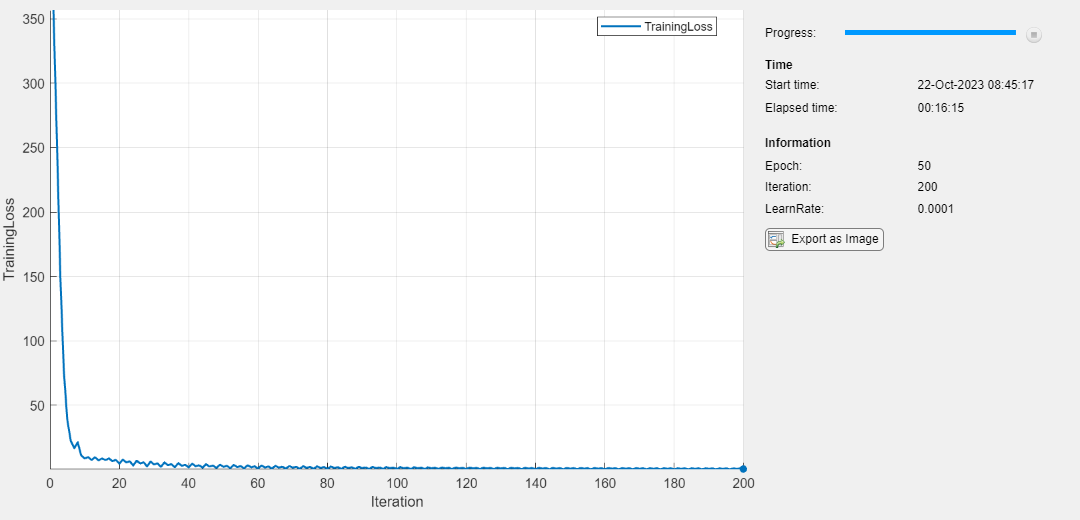

*************************************************************************
Detector training complete.
*************************************************************************



% Train the YOLO v4 network.
detector = trainYOLOv4ObjectDetector(ds,preDetector,options);

save('singleLabel_yolov4_50i_50e.mat','detector');


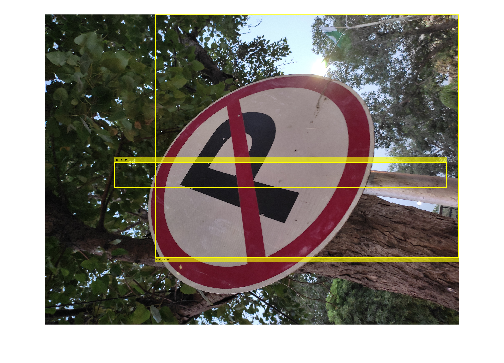

I = imread("D:\college\FYP\Scripts\location\IMG_20230816_185525.jpg");

[bboxes, scores, labels] = detect(detector,I,Threshold=0.05);
detectedImg = insertObjectAnnotation(I,"Rectangle",bboxes,labels,"LineWidth",8,"FontSize",24);
figure
imshow(detectedImg)

function data = preprocessData(data,targetSize)
for num = 1:size(data,1)
    I = data{num,1};
    imgSize = size(I);
    bboxes = data{num,2};
    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    data(num,1:2) = {I,bboxes};
end
end